# 12 Morlet Wavelets and Wavelet Convolution

Two limitations of the Fourier-transform based frequency representation are: 

- Changes in frequency structure over time are difficult to visualize

- EEG data violate the stationarity assumption of Fourier analysis

These two limitations provide motivation to apply time-resolved frequency decomposition of EEG data. A time-resolved frequency representation or time-frequency representation of EEG retains advantages of both the time and frequency domains while making only small and possibly inconsequential sacrifices in temporal and frequency precision. Morlet wavelet convolution is one of several commonly used methods for obtaining time-resolved frequency representations.

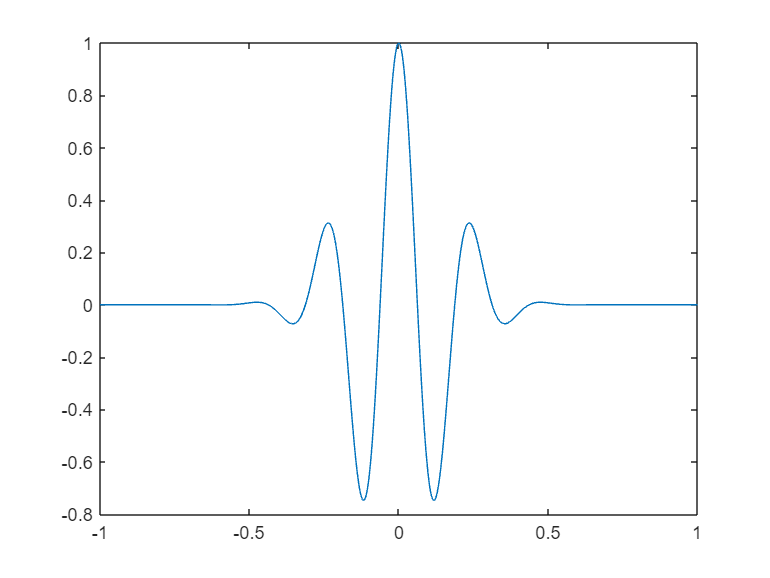

load sampleEEGdata

time = -1:1/EEG.srate:1;
f = 4;

sine_wave = cos(2*pi*f.*time);

s=4/(2*pi*f);
gaussian_win = exp(-time.^2./(2*s^2));

figure
plot(time,sine_wave.*gaussian_win)

**Figure 12.1 **

*A Morlet wavelet, which is created by windowing a sine wave by a Gaussian.*

## 12.1 Why Wavelets? 

The reason the Fourier transform does not show whether and how the frequency characteristics change over time is that the kernel used in the Fourier transform (a sine wave) has no temporal localization; the amplitude of the sine wave continues to fluctuate over its entire time series. To obtain temporally localized frequency information, the dot product with the EEG signal should be computed with only part of a sine wave, specifically the part of a sine wave that occurs at a specific window of time.

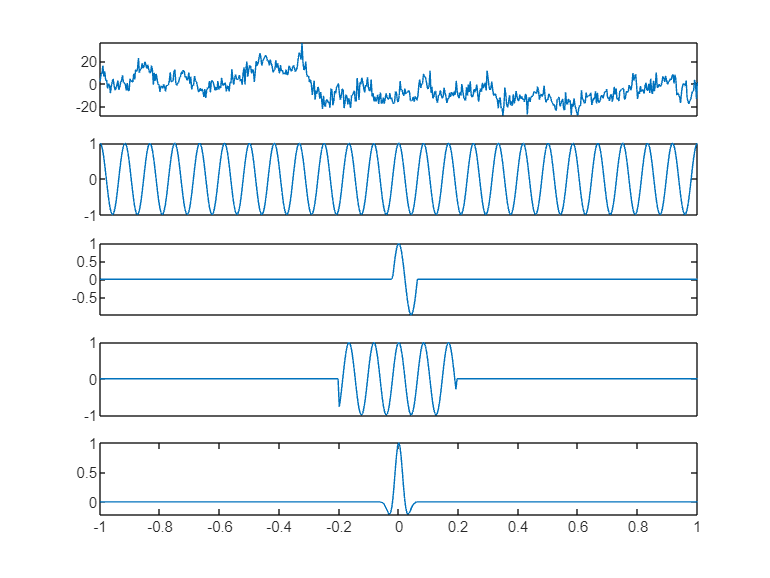

figure
subplot(511)
plot(squeeze(EEG.data(47,:,1)))
set(gca,'XTick',[])
axis tight

subplot(512)
sine_wave = cos(2*pi*12.*time);
plot(sine_wave)
set(gca,'XTick',[])
axis tight

subplot(513)
boxcar = zeros(size(sine_wave));
midpoint = (length(time)-1)/2;
boxcar(midpoint-round(EEG.srate/12/5):midpoint+round(EEG.srate/12/1.25)) = 1;
plot(sine_wave.*boxcar)
set(gca,'XTick',[])
axis tight

subplot(514)
boxcar = zeros(size(sine_wave));
midpoint = (length(time)-1)/2;
boxcar(midpoint-50:midpoint+50) = 1;
plot(sine_wave.*boxcar)
set(gca,'XTick',[])
axis tight

subplot(515)
s=1.5/(2*pi*12); gaussian_win = exp(-time.^2./(2*s^2));
plot(time,sine_wave.*gaussian_win)
axis tight

**Figure 12.2 **

*In order to extract time-varying frequency-specific information from EEG data, the data must be convolved with an appropriate windowed sine wave.*

There are several possible ways to temporally localize dynamic patterns of the frequency structure in a time series: 

- One sine wave cycle: Although the temporal precision is good, the frequency precision is poor. This is related to the trade-off between time and frequency precisions.

- A box-car window around the sine wave: It weights all data points in the box-car area equally and it will produce edge artifacts in the data. 

- A Gaussian window around the sine wave: Gaussian windows have no sharp edges that produce artifacts, dampen the influence of surrounding time points on the estimate of frequency characteristics at each time point, and allow you to control the trade-off between temporal precision and frequency precision.

A sine wave windowed with a Gaussian is called a Morlet wavelet 

There are many different kinds of wavelets, and you can even create your own wavelets. Wavelets must have values at or very close to zero at both ends, and they must have a mean value of zero. However, not all wavelets are useful for time-frequency decomposition of EEG data. Morlet wavelets are well suited for localizing frequency information in time.

There is one final reason to use wavelets. The Fourier transform assumes stationarity of the signal which is violated in EEG data. The stationarity assumption of wavelet convolution is that the signal is stationary only during the time period in which the wavelet looks like a sine wave. EEG data often remain stationary for hundreds of milliseconds. Keep in mind that violations of local stationarity do not invalidate the results of a wavelet convolution, although they will decrease the accuracy of the frequency information.

In Morlet wavelet time-frequency decomposition, The frequency information you obtain at each time point is a weighted sum of the frequency information of surrounding time points, with the weight decreasing with increasing distance away from the center of the wavelet. This should be kept in mind when interpreting time-frequency results. This is not a unique feature of Morlet wavelet convolution but instead is a feature of all time-frequency decomposition methods, including temporal filtering.

## 12.2 How to Make Wavelets 

To make a Morlet wavelet:

- Create a sine wave

- Create a Gaussian

- Multiply them point by point

The sine wave and the Gaussian must have the same number of time points and the same sampling rate (this also needs to be the same sampling rate as the EEG data). The frequency of the wavelet is the frequency of the sine wave. The frequency of a Morlet wavelet is called its peak frequency or center frequency.

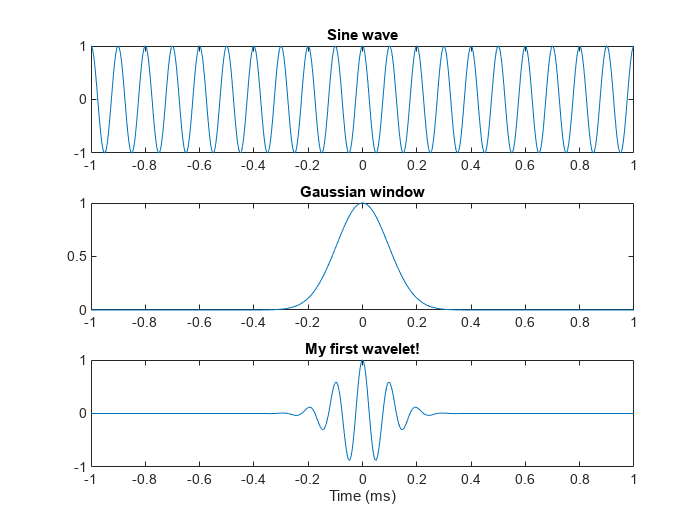

srate = 500;
f = 10;
time = -1:1/srate:1;

sine_wave = exp(2*pi*1i*f.*time);

s = 6/(2*pi*f);
gaussian_win = exp(-time.^2./(2*s^2));

wavelet = sine_wave .* gaussian_win;

figure
subplot(311)
plot(time,real(sine_wave))
title('Sine wave')

subplot(312)
plot(time,gaussian_win)
title('Gaussian window')
 
subplot(313)
plot(time,real(wavelet));
title('My first wavelet!')
xlabel('Time (ms)')

**Figure 12.3**

*A Morlet wavelet (bottom) is a sine wave (top) windowed by a Gaussian (middle).*

The Gaussian window (also sometimes called a bell-shaped or normal curve) is created according to the following formula: 

### 
$$GaussWin=ae^{-{\left(t-m\right)}^2 /\left(2s^2 \right)}$$


- $a$ is amplitude

- $t$ is time

- $m$ is an x-axis offset 

- $s$ is the standard deviation or the width of the Gaussian

The standard deviation of the Gaussian is defined according to bellow equation:

### 
$$s=\frac{n}{2\pi f}$$


- $f$ is frequency (in hertz)

- $n$ is the number of wavelet cycles 

The parameter $n$ defines the trade-off between temporal precision and frequency precision.

Similar to the way a Fourier transform uses many sine waves of different frequencies, time-frequency decomposition via wavelet convolution involves using many wavelets of different frequencies. Unlike Fourier analysis, however, the frequencies of the wavelet can be specified by you rather than being specified by the number of data points in the time series. Furthermore, the number of wavelets that can be used is not constrained — you can use as many wavelets as you want, and those wavelets can have almost any frequency you specify. 

A group of wavelets that share the same properties but differ in frequency is called a family of wavelets. There are a few theoretical and practical limits to constructing a family of wavelets: 

- You cannot use frequencies that are slower than your epochs. 

- The frequencies of the wavelets cannot be above the Nyquist frequency. 

- Because of frequency smoothing from time-frequency precision trade-offs, frequencies that are very close to each other will likely provide similar or nearly identical results.

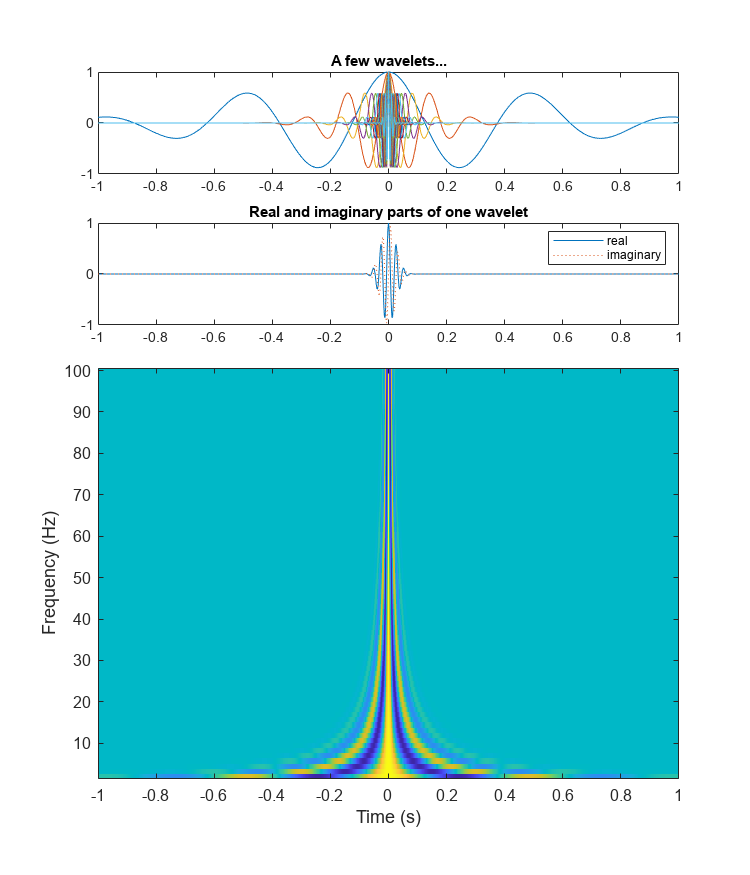

num_wavelets      =  80;
lowest_frequency  =   2;
highest_frequency = 100;

frequencies = linspace(lowest_frequency,highest_frequency,num_wavelets);
wavelet_family = zeros(num_wavelets,length(time));
 
for fi=1:num_wavelets
    wavelet_family(fi,:) = exp(2*1i*pi*frequencies(fi).*time) .* exp(-time.^2./(2*(6/(2*pi*frequencies(fi)))^2));
end

figure(Position=[100,100,600,700])

subplot(511)
plot(time,real(wavelet_family(1:round(rand*30):end,:))') 
title('A few wavelets...')

subplot(512)
plot(time,real(wavelet_family(30,:)))
hold on
plot(time,imag(wavelet_family(30,:)),':')
title('Real and imaginary parts of one wavelet')
legend({'real';'imaginary'})

subplot(5,1,[3,4,5])
imagesc(time,frequencies,real(wavelet_family))
set(gca,'ydir','normal')
xlabel('Time (s)')
ylabel('Frequency (Hz)')

**Figure 12.4 **

*Different members of this wavelet family were created by changing the frequency of the sine wave while leaving other parameters unchanged. *

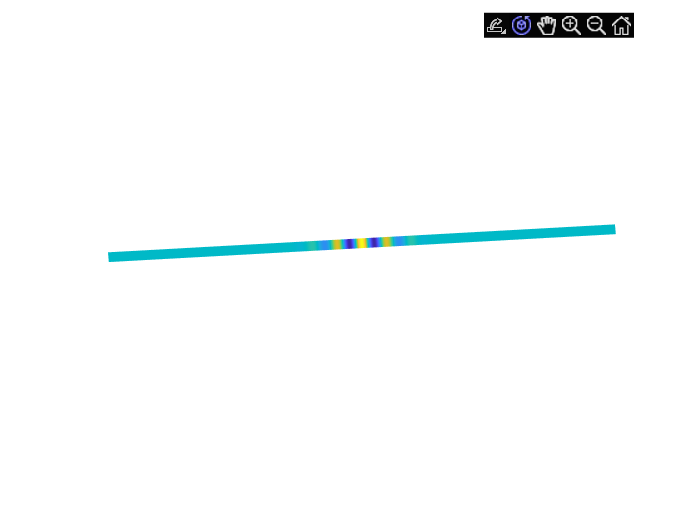

figure, set(gcf,'color','k')
surf(repmat(real(wavelet),2,1))
shading interp
axis off
axis([0 length(time) -20 21 -1 1])
view([ -4 4 ])
 
for i=4:2:90
    view([ -4 i ])
    pause(.1)
end
 
rotate3d

**Figure 12.5**

Movie of a 2-D colored wavelet turning into one line of an image of a family of wavelets.

## 12.3 Wavelet Convolution as a Bandpass Filter 

Convolution can be interpreted as a vector that expresses the time-varying mapping between a kernel and a signal (here: the wavelet and the EEG data).

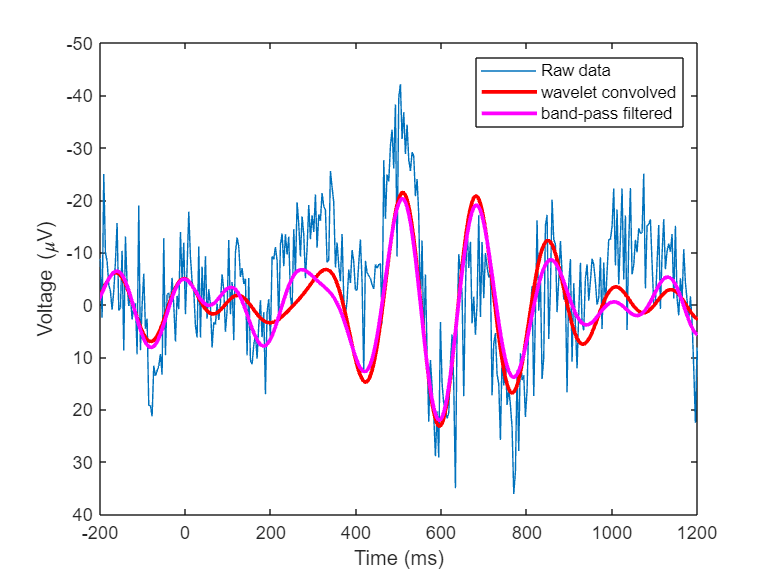

eegdata = squeeze(EEG.data(47,:,10));

time = -1:1/EEG.srate:1;
f = 6;
sine_wave = exp(1i*2*pi*f.*time);
s = 4.5/(2*pi*f); 
gaussian_win = exp(-time.^2./(2*s^2));
wavelet = sine_wave .* gaussian_win;
halfwaveletsize = ceil(length(wavelet)/2);

n_conv = length(wavelet) + EEG.pnts - 1;

fft_w = fft(wavelet,n_conv);
fft_e = fft(eegdata,n_conv);
ift   = ifft(fft_e.*fft_w,n_conv)*sqrt(s)/10;
wavelet_conv_data = real(ift(halfwaveletsize:end-halfwaveletsize+1));

nyquist       = EEG.srate/2;
transition_width = 0.2;
filter_low    = 4;
filter_high   = 8;
ffrequencies  = [ 0 filter_low*(1-transition_width) filter_low filter_high filter_high*(1+transition_width) nyquist ]/nyquist;
idealresponse = [ 0 0 1 1 0 0 ];
filterweights = firls(round(3*(EEG.srate/filter_low)),ffrequencies,idealresponse);
eeg_4to8      = filtfilt(filterweights,1,double(eegdata));

figure

plot(EEG.times,eegdata)
hold on
plot(EEG.times,wavelet_conv_data,'r','linew',2)
plot(EEG.times,eeg_4to8,'m','linew',2)
set(gca,'xlim',[-200 1200],'ydir','r')
xlabel('Time (ms)'), ylabel('Voltage (\muV)')
legend('Raw data','wavelet convolved','band-pass filtered')

**Figure 12.6**

*One trial of EEG data plotted before any filtering (gray line), after being bandpass filtered between 4 and 8 Hz (dashed line), and after being convolved with a 6-Hz Morlet wavelet (black line).*

Convolving EEG data with a wavelet at a specific frequency is similar to bandpass filtering the data around that same frequency. In fact, a Morlet wavelet is a special case of a bandpass filter in which the frequency response is Gaussian-shaped. The spectral representation of a Morlet wavelet has a Gaussian shape around the peak frequency of the wavelet. When the frequency spectrum of the wavelet is multiplied by the frequency spectrum of the EEG data and the inverse Fourier transform is computed, the resulting time series contains the frequency characteristics of the EEG data that are tapered by the frequency characteristics of the wavelet (that is, a Gaussian around the peak frequency).

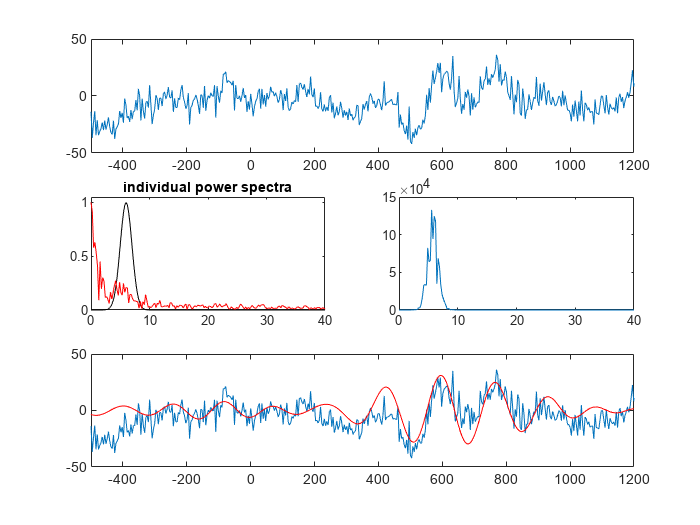

time   = -1:1/EEG.srate:1;
n_conv = EEG.pnts + length(time) - 1;
n2p1   = floor(n_conv/2)+1;

f = 6;
s = 6/(2*pi*f);
wavelet = exp(2*pi*1i*f.*time) .* exp(-time.^2./(2*s^2));
halfwaveletsize = ceil(length(wavelet)/2);

eegdata = squeeze(EEG.data(47,:,10));

figure

subplot(311)
plot(EEG.times,eegdata)
set(gca,'xlim',[-500 1200])

subplot(323)
fft_w = fft(wavelet,n_conv);
hz    = linspace(0,EEG.srate/2,n2p1);
plot(hz,abs(fft_w(1:n2p1))./max(abs(fft_w(1:n2p1))),'k')
hold on

fft_e = fft(eegdata,n_conv);
hz    = linspace(0,EEG.srate/2,n2p1);
plot(hz,abs(fft_e(1:n2p1))./max(abs(fft_e(1:n2p1))),'r')
set(gca,'xlim',[0 40],'ylim',[0 1.05])
title('individual power spectra')

subplot(324)
plot(hz,abs(fft_e(1:n2p1)).*abs(fft_w(1:n2p1)))
set(gca,'xlim',[0 40])

subplot(313)
plot(EEG.times,eegdata)
hold on
ift = ifft(fft_e.*fft_w,n_conv)*sqrt(s)/10;
plot(EEG.times,real(ift(halfwaveletsize:end-halfwaveletsize+1)),'r')
set(gca,'xlim',[-500 1200])

**Figure 12.7**

*Illustration of why wavelet convolution acts as a bandpass filter.*

## 12.4 Limitations of Wavelet Convolution as Discussed Thus Far 

There are two limitations with real-valued Morlet wavelet convolution:

- Convolution with a Morlet wavelet acts as a bandpass filter, but for time-frequency analyses, power and phase information are needed, and these features of the data are not readily apparent in the bandpass-filtered signal.

- The result of convolution with a Morlet wavelet depends on phase offsets between the wavelet and the data. 

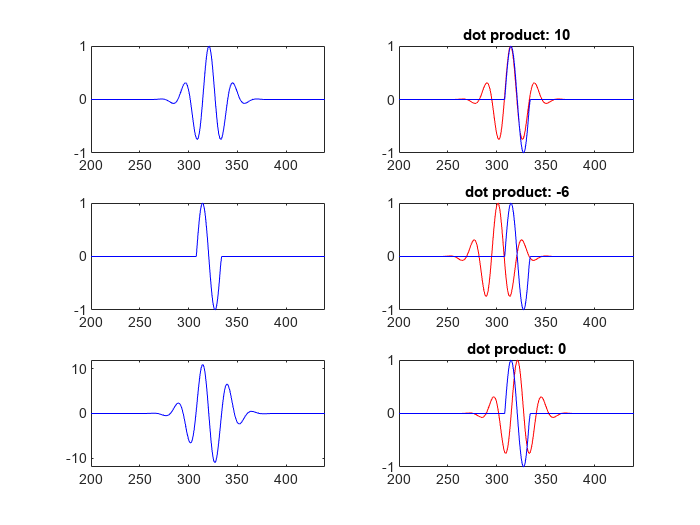

time = -EEG.pnts/EEG.srate/2 : 1/EEG.srate : EEG.pnts/EEG.srate/2-1/EEG.srate;
f    = 10;
s    = 4/(2*pi*f);
wavelet = cos(2*pi*f.*time) .* exp(-time.^2./(2*s^2));

timeS  = 0:1/EEG.srate:(1/f);
signal = sin(2*pi*f.*timeS);

signal = [ zeros(1,EEG.pnts/2-length(timeS)/2) signal zeros(1,EEG.pnts/2-length(timeS)/2) ];

figure

subplot(321)
plot(wavelet, 'b')
set(gca,'xlim',[200 length(time)-200])

subplot(323)
plot(signal, 'b')
set(gca,'xlim',[200 length(time)-200])

subplot(325)
plot(conv(wavelet,signal,'same'), 'b')
set(gca,'xlim',[200 length(time)-200],'ylim',[-12 12])


subplot(322)
plot(wavelet(round(100/f)-2:end),'r')
hold on
plot(signal, 'b')
set(gca,'xlim',[200 length(time)-200])
title([ 'dot product: ' num2str( fix(sum(wavelet(round(100/f)-2:end).*signal(1:end-round(100/f)+3))) ) ])

subplot(324)
plot(wavelet(round(2.3*(100/f)-2):end),'r')
hold on
plot(signal, 'b')
set(gca,'xlim',[200 length(time)-200])
title([ 'dot product: ' num2str( fix(sum(wavelet(round(2.3*(100/f)-2):end).*signal(1:end-round(2.3*(100/f)-3))) )) ])

subplot(326)
plot(wavelet,'r')
hold on
plot(signal, 'b')
set(gca,'xlim',[200 length(time)-200])
title([ 'dot product: ' num2str( fix(sum(wavelet.*signal)) ) ])

**Figure 12.8**

*The result of each step of convolution (the dot product between the wavelet and the data) depends on the phase relationship between the kernel and the signal at that time point. *

In order to resolve both of the limitations of real-valued Morlet wavelets, EEG data are convolved with complex Morlet wavelets— wavelets that have both a real component and an imaginary component. With complex Morlet wavelet convolution, the mapping between the two vectors does not depend on phase lags but, rather, is represented in a 2-D space that allows you to extract not only the bandpass-filtered signal but also time frequency power and phase information. 